## Evaluating Grid Codes using PMU Event Data

To use this tool, select the desired grid code for comparison to PMU data. Select the directory with the event data and a subset of the PMU data recordings to simplify the plot.

selectedCode = 'IEEE1547';
eventFiles = 'PMU_Events/*.csv';
selectedEvents = [1, 4, 7, 11];

The following code plots the grid code and the selected events.

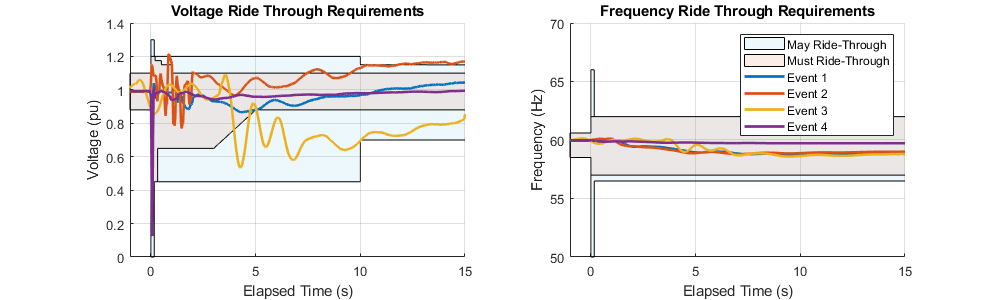

gridCodeDefinitions(); selectedGridCode = eval(['GridCodes.' selectedCode]);
[T,V,F] = importEventData(eventFiles,selectedEvents,selectedGridCode);
gridCodeBounds(selectedGridCode); plotEvents(T,V,F,selectedGridCode);

The following table has information on the required trip time for each event. "May" trip conditions are also included for grid codes with such options, such as IEEE 1547-2018.

TripTable = eventAnalysis(T,V,F,selectedGridCode)

TripTable = 4×5 table
    Event    TripTime    TripType     MayVoltTrip    MayFreqTrip
    _____    ________    _________    ___________    ___________

      1          Inf     "None"             Inf          Inf    
      2      0.83332     "Voltage"      0.83332          Inf    
      3       10.002     "Voltage"       4.0009          Inf    
      4          Inf     "None"        0.066666          Inf    


clearvars eventFiles selectedCode selectedEvents selectedGridCode

## Appendix - Import and Plotting Functions

function gridCodeBounds(selectedCode)

    figure('Position',[0 0 1000 300]); subplot(1,2,1); hold on;
    
    hasMayCondition = detectMayCondition(selectedCode);
    if hasMayCondition
        mayLVRT_T = [selectedCode.mayLVRT.T fliplr(selectedCode.mayHVRT.T)];  
        mayLVRT_V = [selectedCode.mayLVRT.V fliplr(selectedCode.mayHVRT.V)];
        patch(mayLVRT_T,mayLVRT_V,[0.3010    0.7450    0.9330],'FaceAlpha',0.1);
    end
    
    LVRT_T = [selectedCode.LVRT.T fliplr(selectedCode.HVRT.T)];
    LVRT_V = [selectedCode.LVRT.V fliplr(selectedCode.HVRT.V)];
    patch(LVRT_T,LVRT_V,[0.8500    0.3250    0.0980],'FaceAlpha',0.1);
    xlim([-1 15])
    
    grid on
    title('Voltage Ride Through Requirements')
    xlabel('Elapsed Time (s)')
    ylabel('Voltage (pu)')
    
    subplot(1,2,2);
    hold on;
    
    if hasMayCondition
        lowRemove = selectedCode.mayLFRT.T >= -1;     
        highRemove = selectedCode.mayHFRT.T >= -1;
        mayLFRT_T = [selectedCode.mayLFRT.T(lowRemove) fliplr(selectedCode.mayHFRT.T(highRemove))];
        mayLFRT_F = [selectedCode.mayLFRT.F(lowRemove) fliplr(selectedCode.mayHFRT.F(highRemove))];
        patch(mayLFRT_T,mayLFRT_F,[0.3010    0.7450    0.9330],'FaceAlpha',0.1);
    end
        
    lowRemove = selectedCode.LFRT.T >= -1;    highRemove = selectedCode.HFRT.T >= -1;
    LFRT_T = [selectedCode.LFRT.T(lowRemove) fliplr(selectedCode.HFRT.T(highRemove))]; 
    LFRT_F = [selectedCode.LFRT.F(lowRemove) fliplr(selectedCode.HFRT.F(highRemove))];
    patch(LFRT_T,LFRT_F,[0.8500    0.3250    0.0980],'FaceAlpha',0.1); hold off;
    
    xlim([-1 15]); grid on;
    title('Frequency Ride Through Requirements'); xlabel('Elapsed Time (s)'); ylabel('Frequency (Hz)')

end

#### Import Event Data Function

This function uses "readtable" to import data files for event plotting. Event time is found by looking at voltage or frequency values exceeding nominal bounds.

function [Time,Vact,Fact] = importEventData(dirLoc,fileIdx,selectedCode)

    filesList = ls(dirLoc);
    i = 1;
    Time = cell(1,numel(fileIdx)); Vact = Time; Fact = Time;
    for idx = fileIdx
        dataMeas = readtable(filesList(idx,:)); % read csv file
    
        Time{i} = dataMeas.Time;
        Vact{i} = dataMeas.V;
        Fact{i} = dataMeas.F;
    
        findEvent = find(Vact{i} > selectedCode.HVRT.V(1) | Vact{i} < selectedCode.LVRT.V(1) |...
            Fact{i} > selectedCode.HFRT.F(1) | Fact{i} < selectedCode.LFRT.F(1),1,'first');
        if isempty(findEvent)
            iEvent = 1;
        else
            iEvent = findEvent-1;
        end
    
        Time{i} = Time{i} - Time{i}(iEvent);
        Vact{i} = Vact{i};
        i = i + 1;
    end

end

#### Plot Grid Events Function

This function takes the input events (as cell arrays) and plots the respective voltage and frequencies onto the previous figure with the plotted grid code. The selected code is required as an input to account for "may" ride through requirements.

function plotEvents(T,V,F,selectedCode)

    hasMayCondition = detectMayCondition(selectedCode);
    if hasMayCondition
        legendLabels = {'May Ride-Through','Must Ride-Through'}; j = 2;
    else
        legendLabels = {'Must Ride-Through'}; j = 1;
    end
    
    for i = 1:numel(T)
        subplot(1,2,1);  hold on;  plot(T{i},V{i},'LineWidth',2);
        subplot(1,2,2);  hold on;  plot(T{i},F{i},'LineWidth',2);
        legendLabels{i+j} = ['Event ' num2str(i)];
    end
    legend(legendLabels);

end

#### Trip Table Data Table

This function takes the event data and the selected grid code and provides a table with the times that tripping must occur.

function TripTable = eventAnalysis(T,V,F,gridCode)
    
    hasMayCondition = detectMayCondition(gridCode);

    
    MayVoltTrip = zeros(numel(T),1);    TripType = strings(numel(T),1);
    MayFreqTrip = MayVoltTrip;  Event = MayVoltTrip;    TripTime = MayVoltTrip;
    for i = 1:numel(T)

        LV = interp1(gridCode.LVRT.T,gridCode.LVRT.V,T{i});
        HV = interp1(gridCode.HVRT.T,gridCode.HVRT.V,T{i});
        LF = interp1(gridCode.LFRT.T,gridCode.LFRT.F,T{i});
        HF = interp1(gridCode.HFRT.T,gridCode.HFRT.F,T{i});

        idxVoltTrip = find(V{i} > HV | V{i} < LV,1,'first');
        if isempty(idxVoltTrip)
            idxVoltTrip = inf;
        end

        idxFreqTrip = find(F{i} > HF | F{i} < LF,1,'first');
        if isempty(idxFreqTrip)
            idxFreqTrip = inf;
        end

        if hasMayCondition
            mayLV = interp1(gridCode.mayLVRT.T,gridCode.mayLVRT.V,T{i});
            mayHV = interp1(gridCode.mayHVRT.T,gridCode.mayHVRT.V,T{i});
            mayLF = interp1(gridCode.mayLFRT.T,gridCode.mayLFRT.F,T{i});
            mayHF = interp1(gridCode.mayHFRT.T,gridCode.mayHFRT.F,T{i});

            idxMayVoltTrip = find(V{i} > mayHV | V{i} < mayLV,1,'first');
            if isempty(idxMayVoltTrip)
                idxMayVoltTrip = inf;
            end

            idxMayFreqTrip = find(F{i} > mayHF | F{i} < mayLF,1,'first');
            if isempty(idxMayFreqTrip)
                idxMayFreqTrip = inf;
            end

            [idxTrip,voltOrFreq] = min([idxMayVoltTrip;idxMayFreqTrip]);
            if isinf(idxTrip)
                timeTrip = inf;
            else
                timeTrip = T{i}(idxTrip);
            end
            
            if isinf(idxVoltTrip)
                MayVoltTrip(i) = inf;
            else
                MayVoltTrip(i) = T{i}(idxVoltTrip);
            end
            if isinf(idxFreqTrip)
                MayFreqTrip(i) = inf;
            else
                MayFreqTrip(i) = T{i}(idxFreqTrip);
            end  
            
        else
            [idxTrip,voltOrFreq] = min([idxVoltTrip;idxFreqTrip]);
            if isinf(idxTrip)
                timeTrip = inf;
            else
                timeTrip = T{i}(idxTrip);
            end
        end

        Event(i) = i;
        TripTime(i) = timeTrip;
        if voltOrFreq == 1 && ~isinf(timeTrip)
            TripType(i) = "Voltage";
        elseif voltOrFreq == 2 && ~isinf(timeTrip)
            TripType(i) = "Frequency";
        else
            TripType(i) = "None";
        end
        
    end

    if hasMayCondition
        TripTable = table(Event,TripTime,TripType,MayVoltTrip,MayFreqTrip);
    else
        TripTable = table(Event,TripTime,TripType);
    end
end

#### Grid Codes with "May" Conditions

This function checks if the selected grid code has a "may" condition, such as IEEE 1547.

function hasMayCondition = detectMayCondition(selectedCode)
    unpackStruct = fieldnames(selectedCode);
    hasMayCondition = sum(contains(unpackStruct,'may')) > 0;
end